Figure 3A

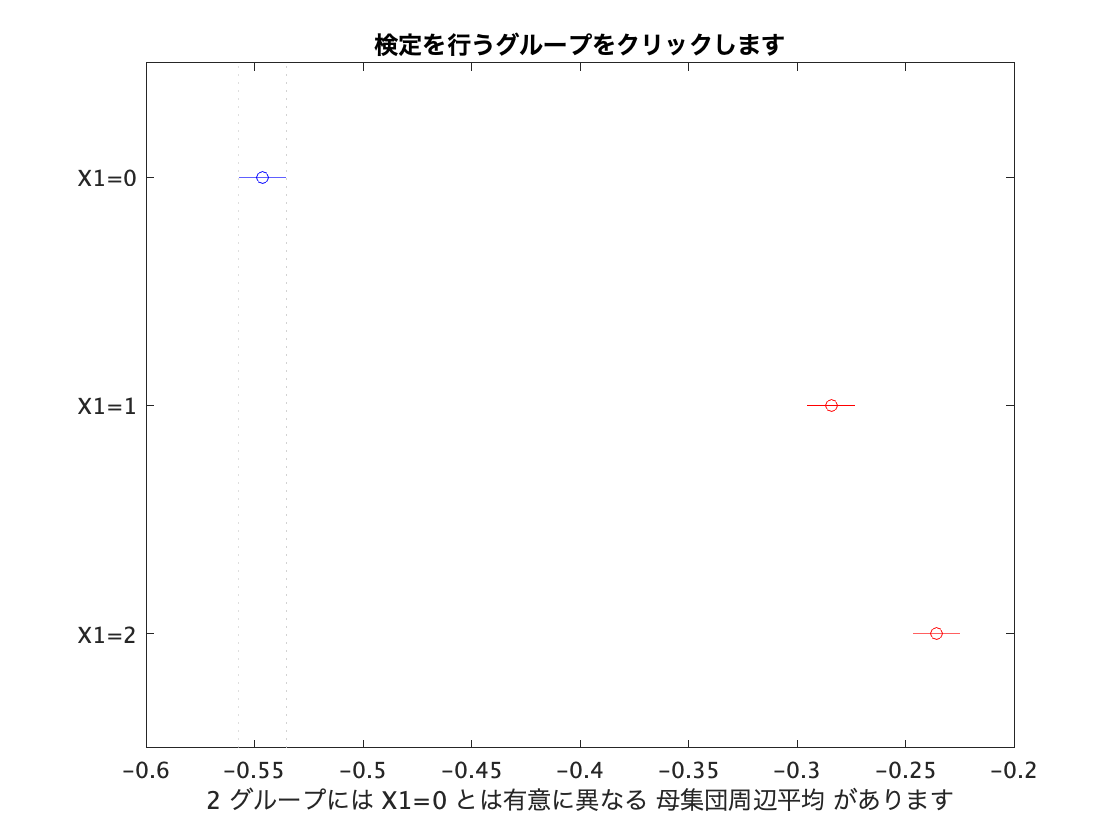

% set index = 1 (max PHI) in MC_import
% set index = 2 (sum PHI) in MC_import

MC_import

active_phi = zeros(18, time);
passive_phi = zeros(18, time);
control_phi = zeros(18, time);

for ind = 1 :18
    active_phi(ind, :) = movmean(active_PHI(ind, :), 50);
    passive_phi(ind, :) = movmean(passive_PHI(ind, :), 50);
    control_phi(ind, :) = movmean(control_PHI(ind, :), 50);
end

% Blue-Moderate: Red-Difficult: Yellow-Easy
result = [mean(active_phi);mean(passive_phi);mean(control_phi)].';

writematrix(result, "maxPhi_series_" + num2str(interval) + ".csv");

hold off

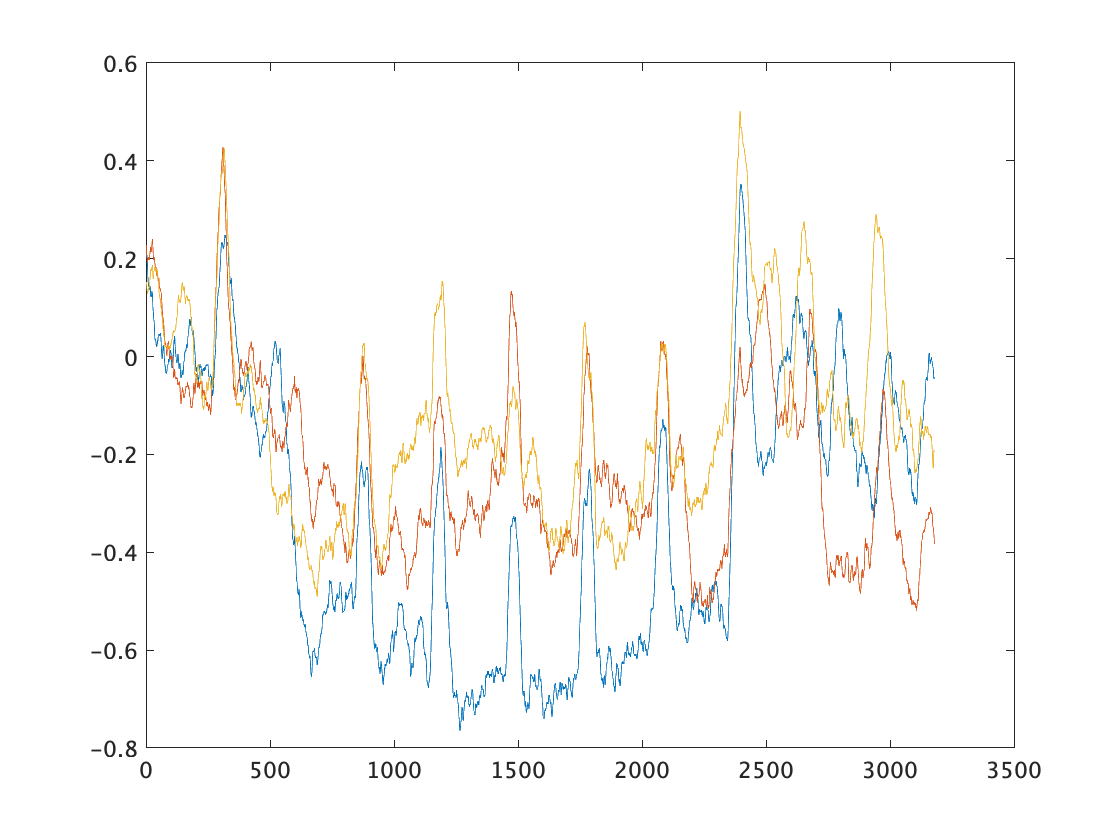

plot(mean(active_phi))
hold on
plot(mean(passive_phi))
plot(mean(control_phi))
hold off

Figure 3B

% set index = 4 (sum PHI) in MC_import

MC_import

MC_type = unique([unique_without_nan(active_MC); ...
    unique_without_nan(passive_MC); unique_without_nan(control_MC)]); 

times = 1: time1;

inter = size(active_PHI(:,times), 2);
active_bf = reshape(active_MC(:, times), [1, inter*18]);
passive_bf = reshape(passive_MC(:, times), [1, inter*18]);
control_bf = reshape(control_MC(:, times), [1, inter*18]);

active_mip_bf = reshape(active_PHI(:, times), [1, inter*18]);
passive_mip_bf = reshape(passive_PHI(:, times), [1, inter*18]);
control_mip_bf = reshape(control_PHI(:, times), [1, inter*18]);

times = time1:time2;

inter = size(active_MC(:,times), 2);
active_task = reshape(active_MC(:, times), [1, inter*18]);
passive_task = reshape(passive_MC(:, times), [1, inter*18]);
control_task = reshape(control_MC(:, times), [1, inter*18]);

active_mip_task = reshape(active_PHI(:, times), [1, inter*18]);
passive_mip_task = reshape(passive_PHI(:, times), [1, inter*18]);
control_mip_task = reshape(control_PHI(:, times), [1, inter*18]);

times = time2:3173;

inter = size(active_MC(:,times), 2);
active_af = reshape(active_MC(:, times), [1, inter*18]);
passive_af = reshape(passive_MC(:, times), [1, inter*18]);
control_af = reshape(control_MC(:, times), [1, inter*18]);

active_mip_af = reshape(active_PHI(:, times), [1, inter*18]);
passive_mip_af = reshape(passive_PHI(:, times), [1, inter*18]);
control_mip_af = reshape(control_PHI(:, times), [1, inter*18]);


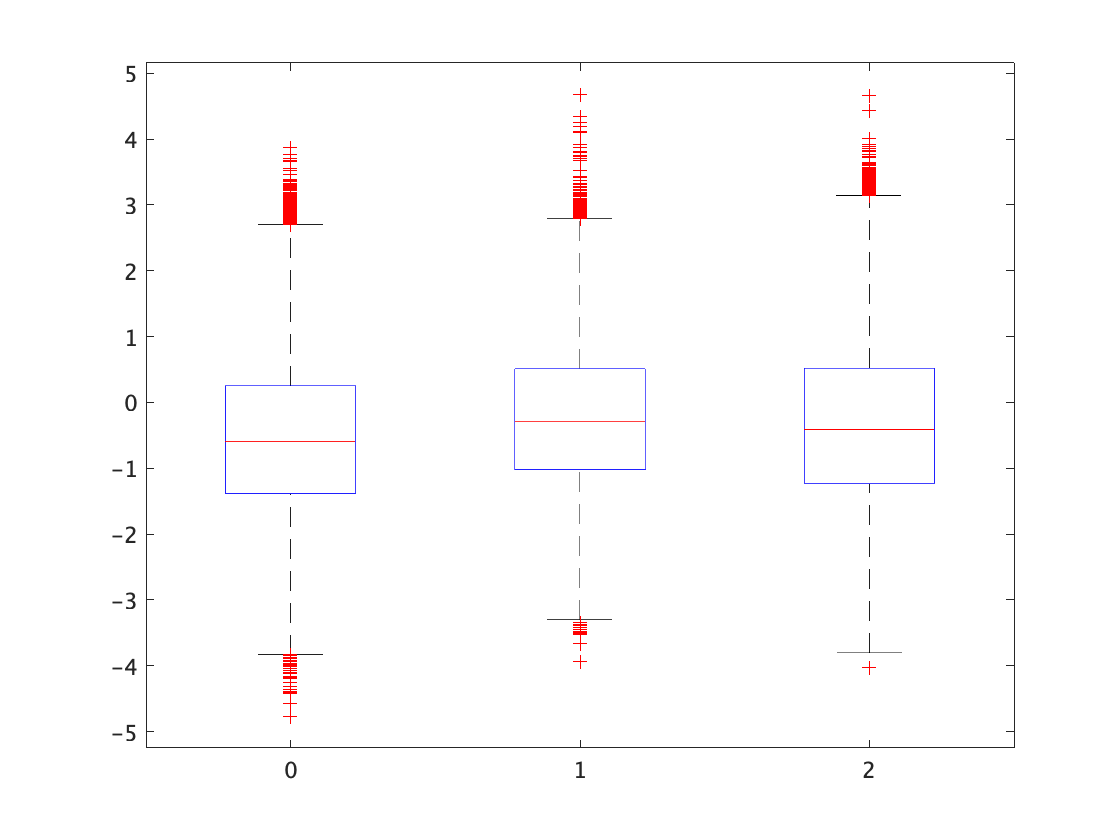

% Fig SUMPHI during task

x1 = active_mip_task.';
x2 = passive_mip_task.';
x3 = control_mip_task.';
x = [x1; x3; x2];
g = [zeros(length(x1), 1); ones(length(x3), 1); 2*ones(length(x2), 1)];
boxplot(x, g)


% Moderate, Easy, Difficult
[mean(x1), mean(x3), mean(x2) ]

ans =    -0.5462   -0.2357   -0.2840


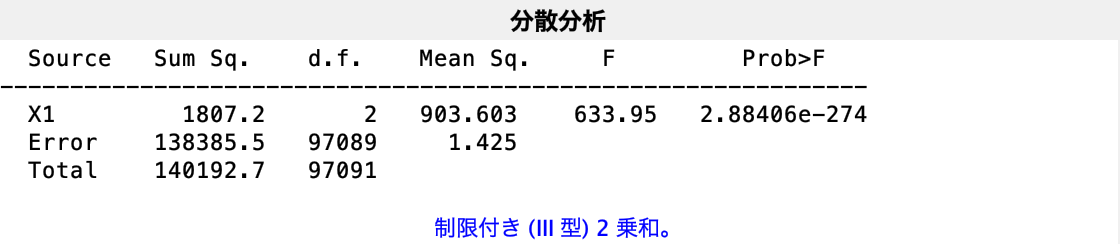

[p,tbl,stats] = anovan(x, g);

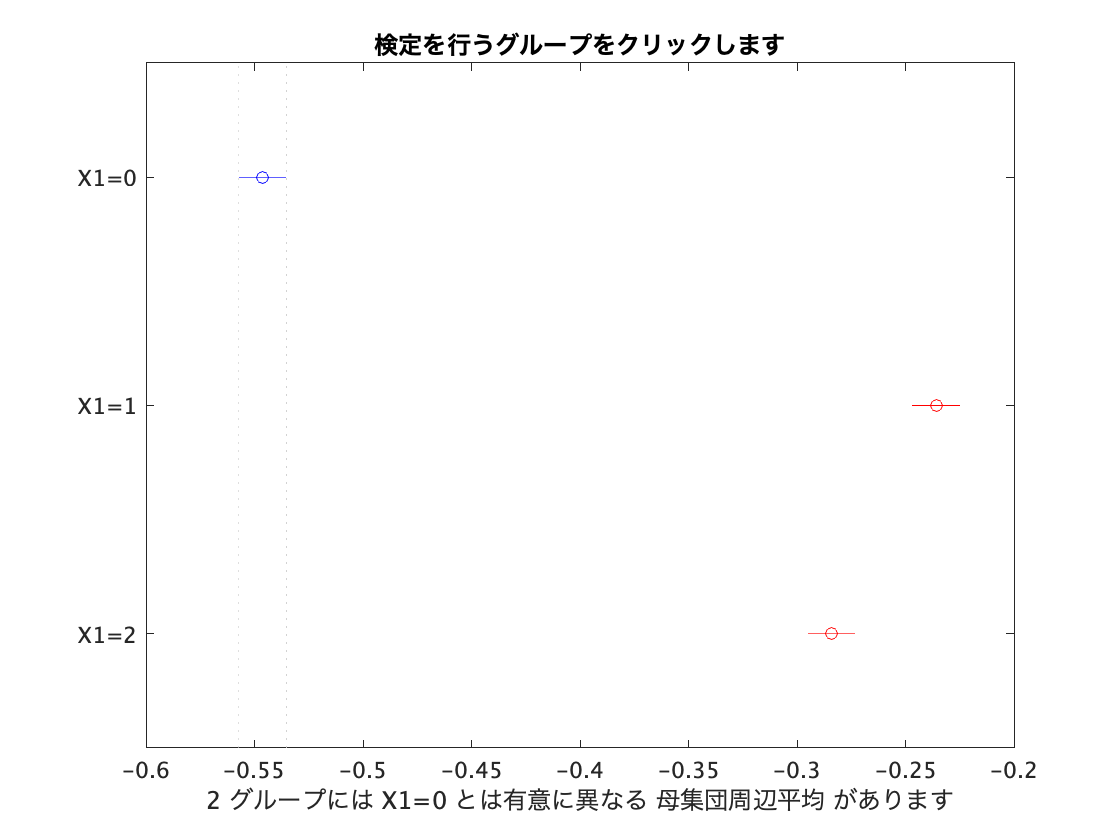

c =     1.0000    2.0000   -0.3325   -0.3105   -0.2885    0.0000
    1.0000    3.0000   -0.2842   -0.2622   -0.2402    0.0000
    2.0000    3.0000    0.0263    0.0483    0.0703    0.0000


c = multcompare(stats)

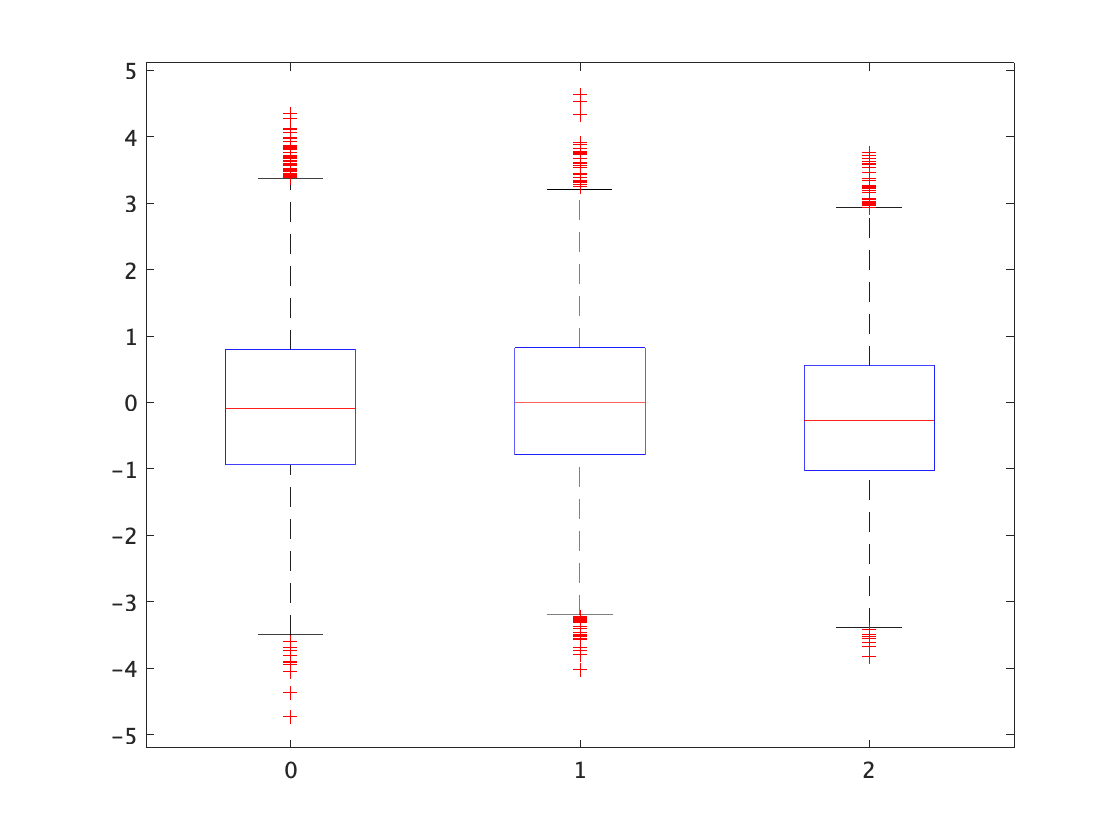

% Fig SUMPHI post task

x1 = active_mip_af.';
x2 = passive_mip_af.';
x3 = control_mip_af.';
x = [x1; x3; x2];
g = [zeros(length(x1), 1); ones(length(x3), 1); 2*ones(length(x2), 1)];
boxplot(x, g)


% Moderate, Difficult, Easy
[mean(x1), mean(x3), mean(x2)]

ans =    -0.0780    0.0270   -0.2212


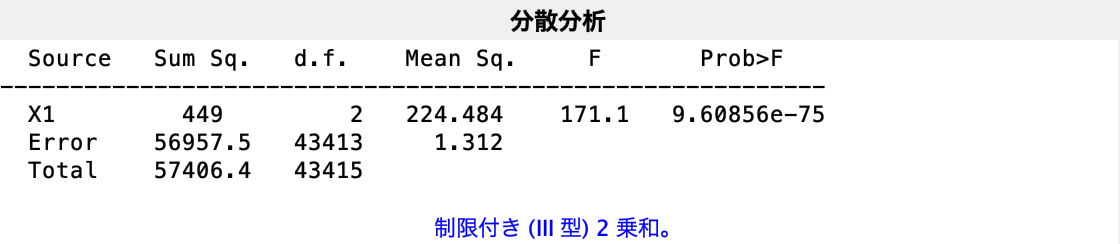

[p,tbl,stats] = anovan(x, g);

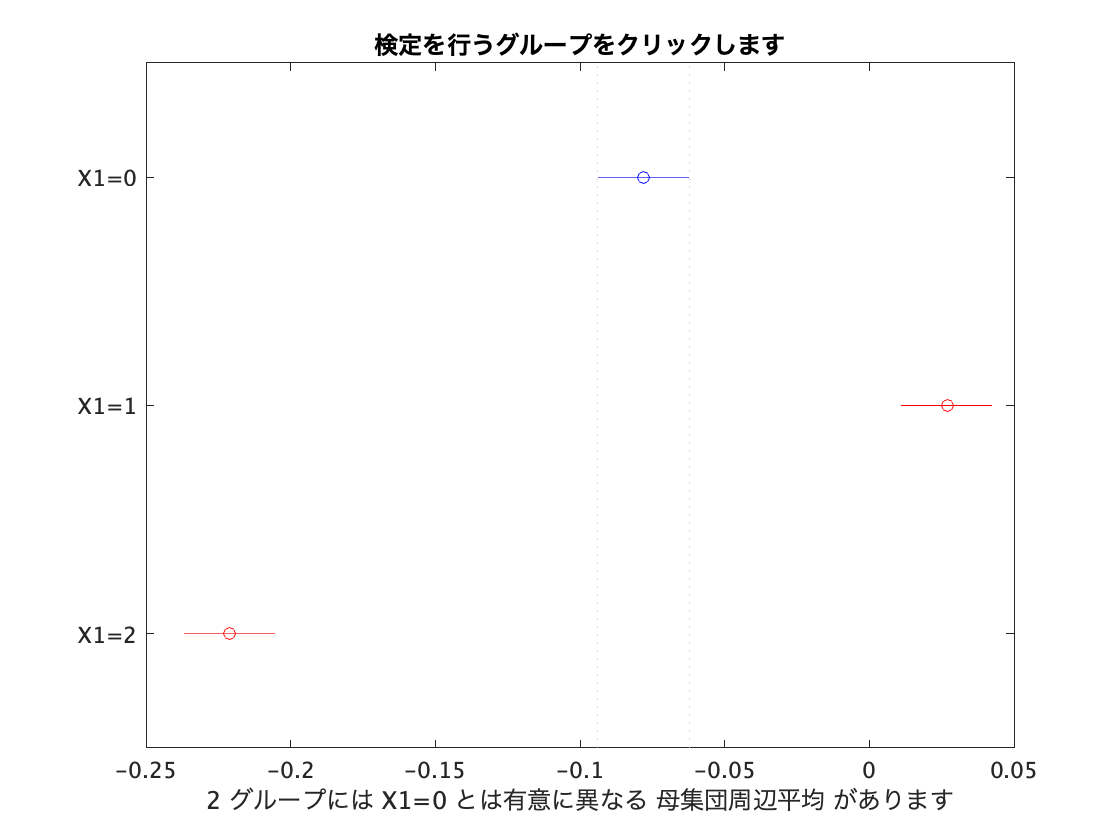

c =     1.0000    2.0000   -0.1365   -0.1050   -0.0734    0.0000
    1.0000    3.0000    0.1116    0.1431    0.1747    0.0000
    2.0000    3.0000    0.2166    0.2481    0.2797    0.0000


c = multcompare(stats)

Figure 3C

メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


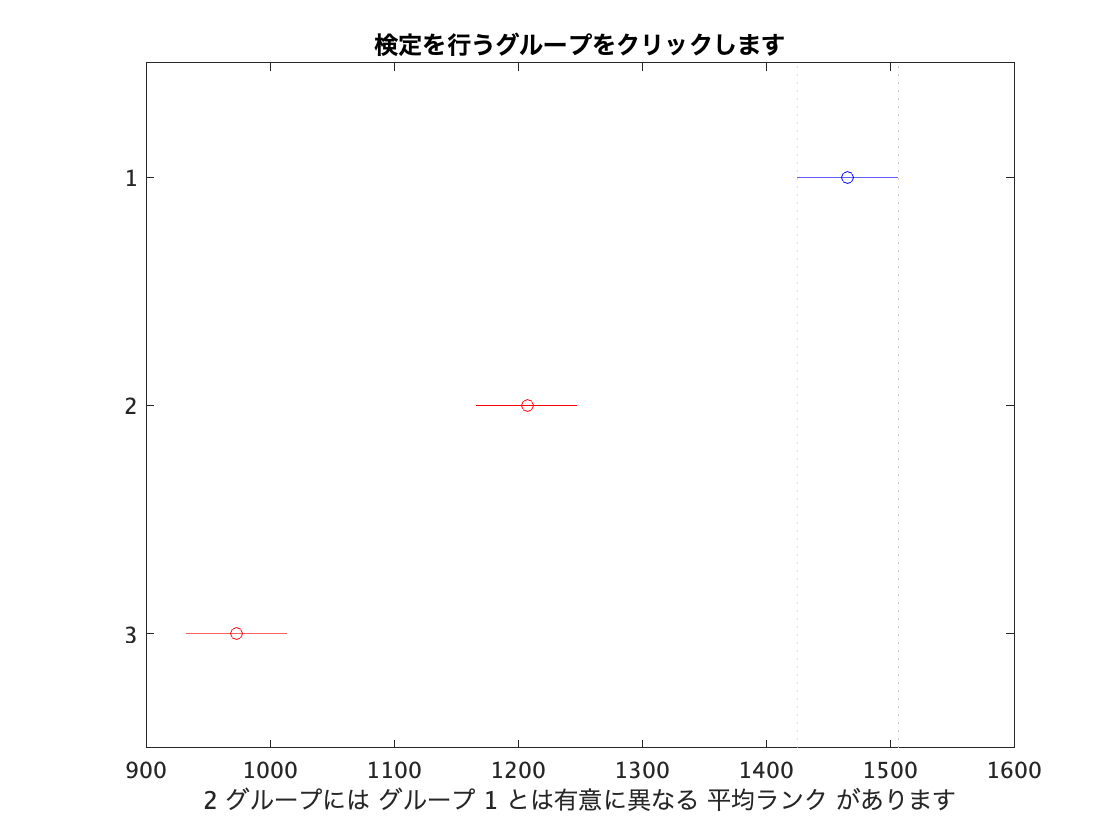

% set time
t1 = times(2);  t2= times(3); t_end=times(1);
t1_interval = 1:t1; t2_interval = t1:t2; t3_interval = t2:t_end;

task_phi_ind = zeros(18, 3);
post_phi_ind = zeros(18, 3);

p_values_task = zeros(18, 3);
p_values_post = zeros(18, 3);

for ind = 1 : 18
    X2 = [active_PHI(ind, t2_interval); control_PHI(ind, t2_interval); passive_PHI(ind, t2_interval)].';
    X3 = [active_PHI(ind, t3_interval); control_PHI(ind, t3_interval); passive_PHI(ind, t3_interval)].';

    task_phi_ind(ind, : ) = mean(X2);
    post_phi_ind(ind, : ) = mean(X3);

    [p2,tbl,stats] = kruskalwallis(X2,[],'off');
    c = multcompare(stats);
    p_values_task(ind, :) = c(:, 6).';
    [p3,tbl,stats] = kruskalwallis(X3,[],'off');
    c = multcompare(stats);
    p_values_post(ind, :) = c(:, 6).';
end

%% Order
% 1-Moderate 2-Easy 3-Difficult
% active-control, active-passive, control-passive

series = zeros(1, 6);
series2 = zeros(1, 6);

type_series = [[1, 2, 3]; [1, 3, 2]; [2, 1, 3]; [2, 3, 1]; [3, 1, 2]; [3, 2, 1]];

 [~, index] = sort(task_phi_ind,2);
 [~, index2] = sort(post_phi_ind,2);

 for ind = 1 : 18
     for j = 1: 6
         if sum(type_series(j, : ) == index(ind, :)) == 3
             series(j) = series(j) + 1;
         end
         if sum(type_series(j, : ) == index2(ind, :)) == 3
             series2(j) = series2(j) + 1;
         end
     end
 end
 
 X = [[series/sum(series);series2/sum(series2)].']

X =     0.2222    0.1667
    0.4444    0.1111
    0.1111    0.0556
         0    0.1111
    0.0556    0.2778
    0.1667    0.2778


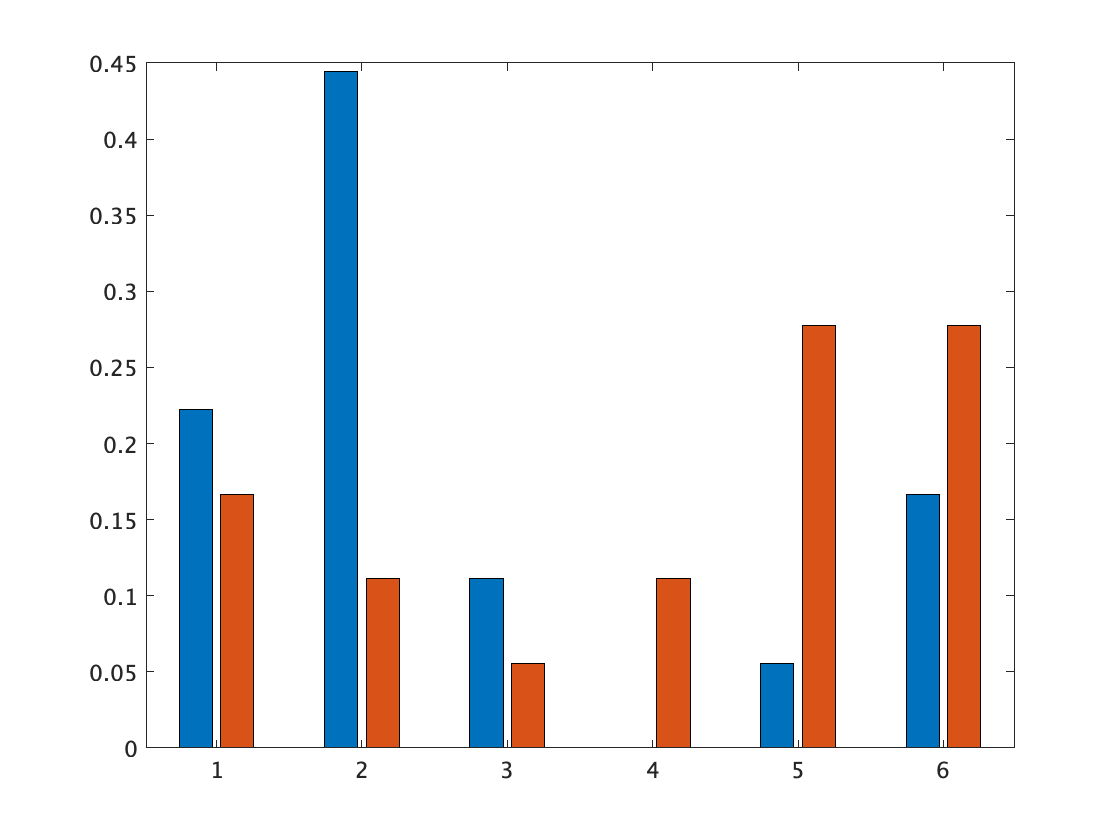

 
 bar(X)

Figure 4

% set index = 4 (sum PHI) in MC_import

MC_import;

MC_type = unique([unique_without_nan(active_MC); ...
    unique_without_nan(passive_MC); unique_without_nan(control_MC)]);

MC_frequency_Prev = zeros(3, size(MC_type, 1), 18);
MC_frequency_Stim = zeros(3, size(MC_type, 1), 18);
MC_frequency_Post = zeros(3, size(MC_type, 1), 18);

% 時間設定
t1 = times(2);  t2= times(3); t_end=times(1);
t1_interval = 1:t1; t2_interval = t1:t2; t3_interval = t2:t_end;

T1 = length(t1_interval);
T2 = length(t2_interval);
T3 = length(t3_interval);


for ind = 1 :18
    for i = 1 : length(MC_type)
        MC_frequency_Prev(1, i, ind) = sum(active_MC(ind, t1_interval)==MC_type(i))/T1;
        MC_frequency_Prev(2, i, ind) = sum(passive_MC(ind, t1_interval)==MC_type(i))/T1;
        MC_frequency_Prev(3, i, ind) = sum(control_MC(ind, t1_interval)==MC_type(i))/T1;
    
        MC_frequency_Stim(1, i, ind) = sum(active_MC(ind, t2_interval)==MC_type(i))/T2;
        MC_frequency_Stim(2, i, ind) = sum(passive_MC(ind, t2_interval)==MC_type(i))/T2;
        MC_frequency_Stim(3, i, ind) = sum(control_MC(ind, t2_interval)==MC_type(i))/T2;
    
        MC_frequency_Post(1, i, ind) = sum(active_MC(ind, t3_interval)==MC_type(i))/T3;
        MC_frequency_Post(2, i, ind) = sum(passive_MC(ind, t3_interval)==MC_type(i))/T3;
        MC_frequency_Post(3, i, ind) = sum(control_MC(ind, t3_interval)==MC_type(i))/T3;
    end
end

%%
mean_stim_bar = zeros(length(MC_type), 3);
MC_list = [];

for j = 1 : length(MC_type)
    count = [0, 0, 0];
    for i = 1 : 3
        A = reshape(MC_frequency_Stim(i, j, :) - MC_frequency_Prev(i, j, :), [18, 1]);
        [s, p] = ttest(A, zeros(18,1));
        mean_stim_bar(j, i) = mean(A);
        if p < 0.05
            count(i) = 1;
        end
    end
    if sum(count) >= 3
        MC_list = [MC_list, j];
         bit_seq_rev(MC_type(j))
        count
    end
end

ans = 1×2 の string 配列
    "Cz"    "Pz"


count =      1     1     1


ans = 1×3 の string 配列
    "Fz"    "Cz"    "EDA"


count =      1     1     1


ans = 1×4 の string 配列
    "Fz"    "Cz"    "Pz"    "EDA"


count =      1     1     1



mean_post_bar = zeros(length(MC_type), 3);
MC_list = [];

for j = 1 : length(MC_type)
    count = [0, 0, 0];
    for i = 1 : 3
        A = reshape(MC_frequency_Post(i, j, :) - MC_frequency_Prev(i, j, :), [18, 1]);
        [s, p] = ttest(A, zeros(18,1));
        mean_post_bar(j, i) = mean(A);
        if p < 0.05
            count(i) = 1;
        end
    end
    if sum(count) >= 1
        MC_list = [MC_list, j];
        count
    end
end

count =      0     1     0


count =      0     1     0


count =      0     0     1


count =      1     0     0


count =      1     0     0


count =      0     1     0


count =      1     0     0


count =      0     0     1


count =      1     0     0


count =      0     1     0


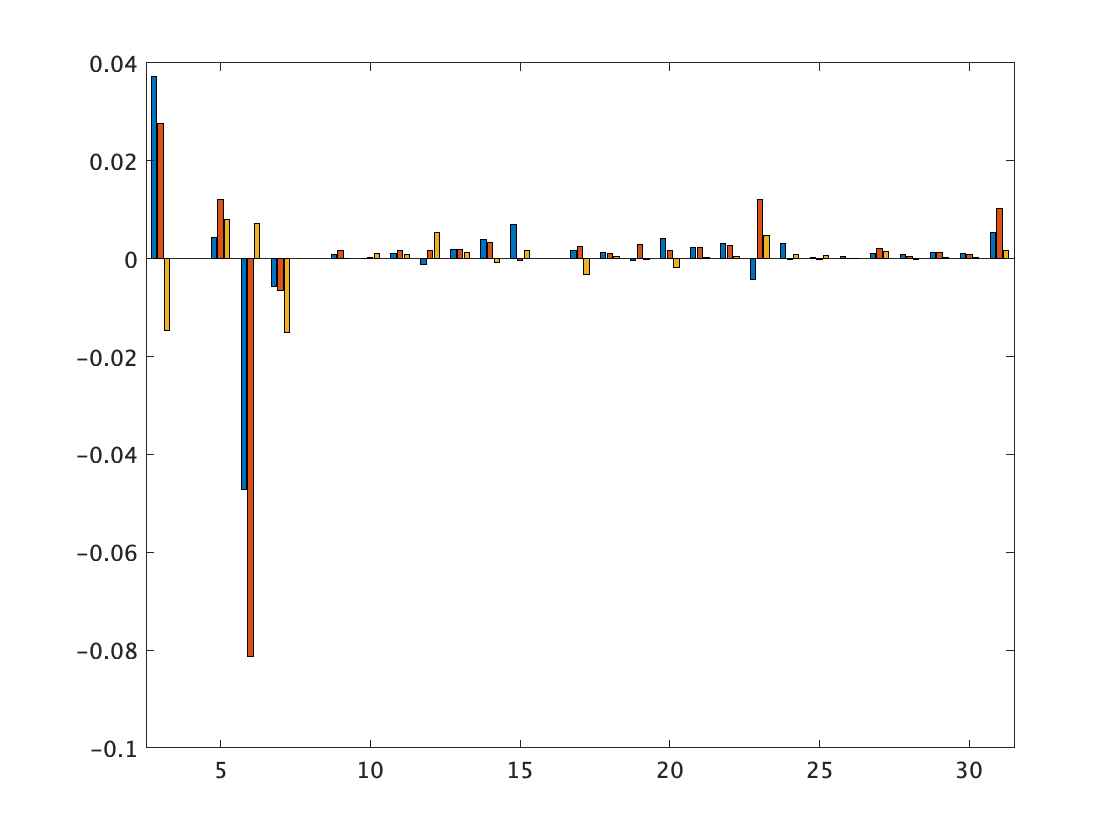


bar(MC_type, mean_post_bar)